clf reset
clc
lab_data_4v = readtable("comb_part1_4v.csv");
simu_v4k100 = readtable("100k4v_simu.csv");
simu_v4k20 = readtable("20k4v_simu.csv");

real_t_1_4v = table2array(lab_data_4v(:,"t_in_100"));
real_t_2_4v = table2array(lab_data_4v(:,"t_out_100"));
real_v_in_100k_4v = table2array(lab_data_4v(:,"v_in_100"));
real_v_out_100k_4v = table2array(lab_data_4v(:,"v_out_100"));
real_v_in_20k_4v = table2array(lab_data_4v(:,"v_in_20"));
real_v_out_20k_4v = table2array(lab_data_4v(:,"v_out_20"));

simu_v_in_100k_4v = table2array(simu_v4k100(:,"vin_simu_100k_4v"));
simu_v_out_100k_4v = table2array(simu_v4k100(:,"vout_simu_100k_4v"));
simu_v_in_20k_4v = table2array(simu_v4k20(:,"vin_20k_4v"));
simu_v_out_20k_4v = table2array(simu_v4k20(:,"vout_20k_4v"));

100k real vs simu

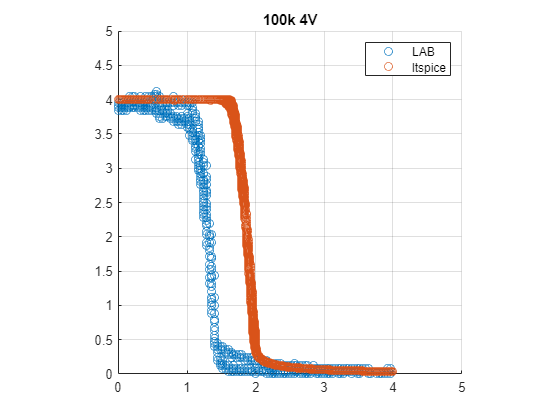

hold on
scatter(real_v_in_100k_4v, real_v_out_100k_4v)
scatter(simu_v_in_100k_4v, simu_v_out_100k_4v)
title("100k 4V")
grid on
axis square
xlim([0 5])
ylim([0 5])
legend("LAB", "ltspice")
hold off

20K real vs simu

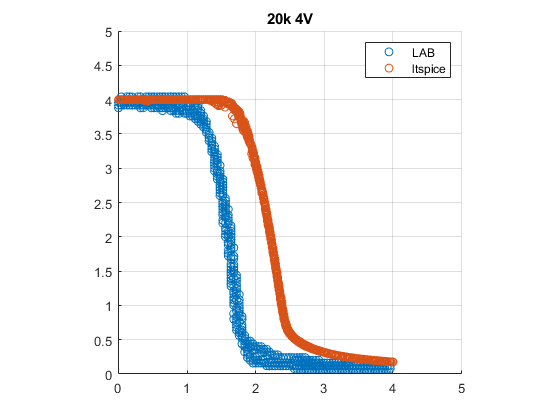

figure
hold on
scatter(real_v_in_20k_4v, real_v_out_20k_4v)
scatter(simu_v_in_20k_4v, simu_v_out_20k_4v)
title("20k 4V")
grid on
axis square
xlim([0 5])
ylim([0 5])
legend("LAB", "ltspice")
hold off

100k real vs real

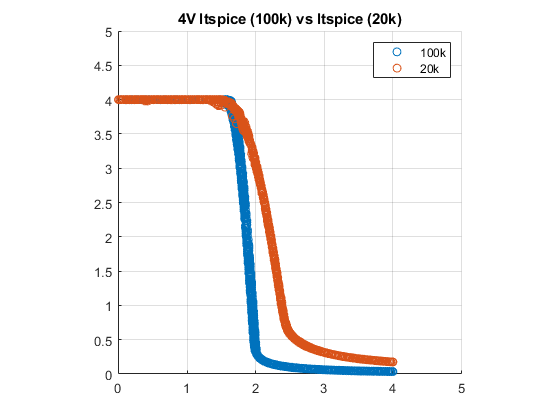

figure
hold on
scatter(simu_v_in_100k_4v, simu_v_out_100k_4v)
scatter(simu_v_in_20k_4v, simu_v_out_20k_4v)
title("4V ltspice (100k) vs ltspice (20k)")
grid on
axis square
xlim([0 5])
ylim([0 5])
legend("100k", "20k")
hold off

100k simu vs simu

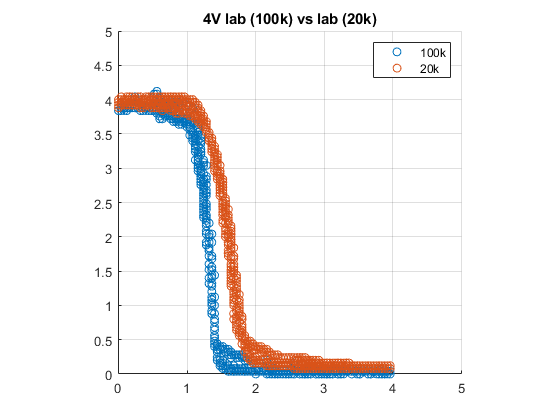

figure
hold on
scatter(real_v_in_100k_4v, real_v_out_100k_4v)
scatter(real_v_in_20k_4v, real_v_out_20k_4v)
title("4V lab (100k) vs lab (20k)")
grid on
axis square
xlim([0 5])
ylim([0 5])
legend("100k", "20k")
hold off

YT plots

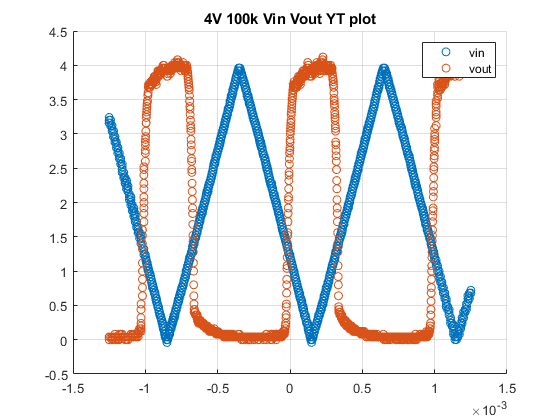

figure
hold on
scatter(real_t_1_4v, real_v_in_100k_4v)
scatter(real_t_2_4v, real_v_out_100k_4v)
title("4V 100k Vin Vout YT plot")
grid on
legend("vin", "vout")
hold off

Find critical points

function [v_oh, v_ol, v_ih, v_il v_th] = find_crit_points(input_voltage, output_voltage)
    vtc = output_voltage / input_voltage;
end